# Deterministic Chaos

There is a class of nonlinear systems of ordinary differential equations that exhibit a very strange and disturbing behavior; deterministic chaos.  The solutions of the equations appear random, but there are no stachastic or random terms in the equations (hence this phenomenon is called *deterministic* chaos). Many systems of differential equations found in the Earth and environmetnal sciences display this behavior, including simplified models of atmospheric motions and population dynamics models.

## The Lorenz System

The Lorenz system system is an approximation to the full equations describing thermal convection in a fluid. These equations were developed by hte meteorlogist Edward Lorenz as a simplified description of atmospheric convection. There are three, first order differential equations


$$\frac{dx}{dt} = \sigma(y-x), \qquad \frac{dy}{dt} = x(r-z) - y, \qquad \frac{dz}{dt} = xy - bz$$


where $\sigma,\,r,\,b$ are all parameters. For certain values of these parameters, the Lorenz system displays chaotic behavior.

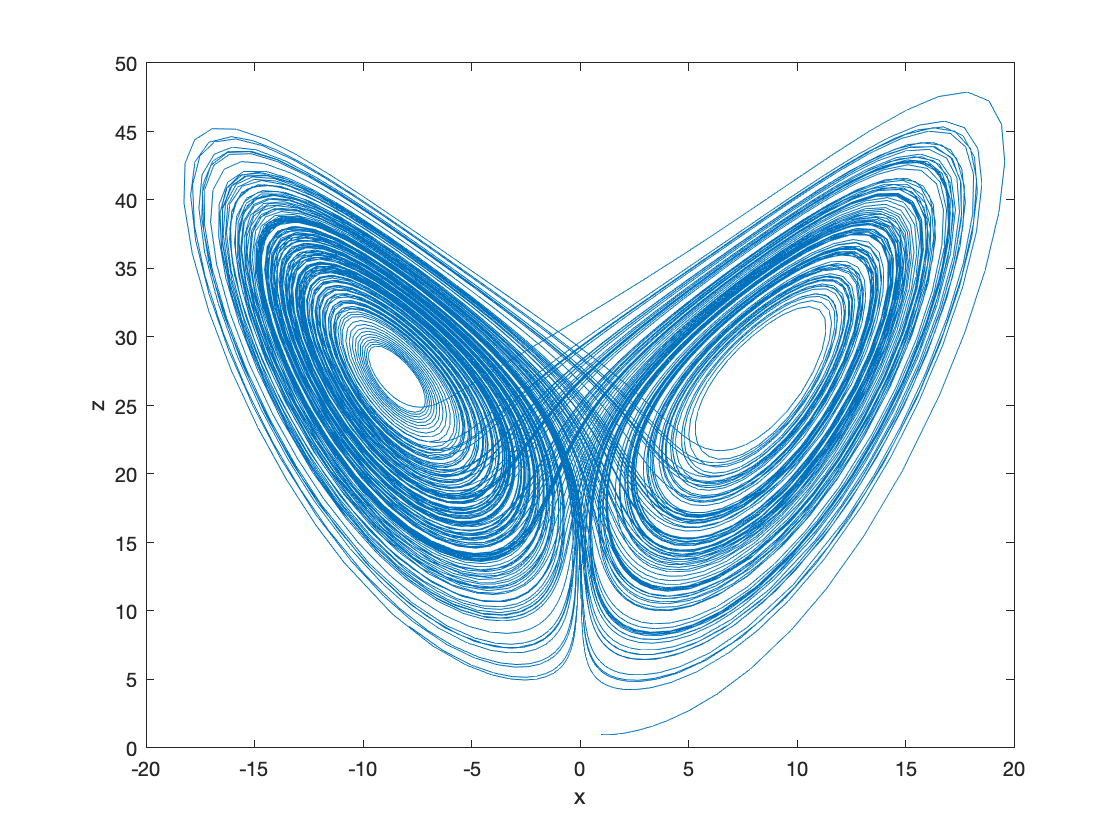

% Set the values of the parameters. The values s = 10.0, b=8/3, r=28.0 produces the standard butterfly diagram.  
s = 10.0;
b = 8.0/3.0;
r = 28.0;
 
% Set the initial and final times and the initial conditions.
t_init = 0.0;
t_final = 200.0;
t_span = [t_init t_final];
 
y_init = [1.0; 1.0; 1.0];
 

% Solve the equations using Matlab's ode45 routine. 
[t,y] = ode45(@(t,y) LorenzEqns(t, y, s, b, r), t_span, y_init);
 
% Plot the results. 
figure
plot(y(:,1), y(:,3))
xlabel('x');
ylabel('z');

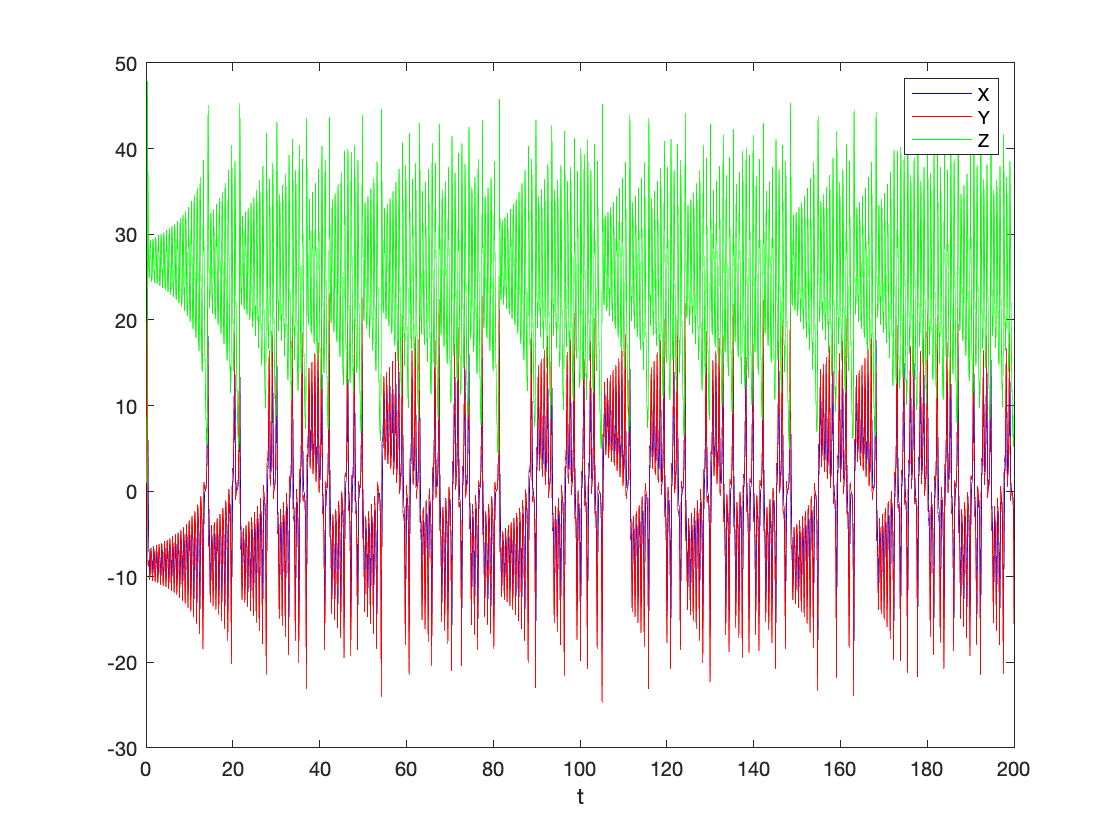

 
figure
plot(t, y(:,1), 'b', t, y(:,2), 'r', t, y(:,3), 'g')
xlabel('t')
legend('X', 'Y', 'Z')

The values for the parameters chosen in the above code produce the standard chaotic model with the beautiful "butterfly wing" pattern. If you examine the x,y, and z trajectories you will see that the trajectories appear quite random.

***Exercise:**** Re-run the model but for r = 20.0 and compare your results to those above. *

A great deal of work has been done in understanding how deterministic chaotic behavior arises and what its consequenses are. There are many reasons for this. It is an inherently fascinating topic, as well as being something of a surprise. It is also important to understand because some important natural phenomenon may be described using equation that show chaotic behavior, and so to understand and hope to predict these phenomena requires understanding the chaotic nature of their solutions. 

## Sensitive Dependence on Initial Condition

We can get an inkling of how chaos arises in the Lorenz system by solving the equations for two sets of initial conditions that are very close together.

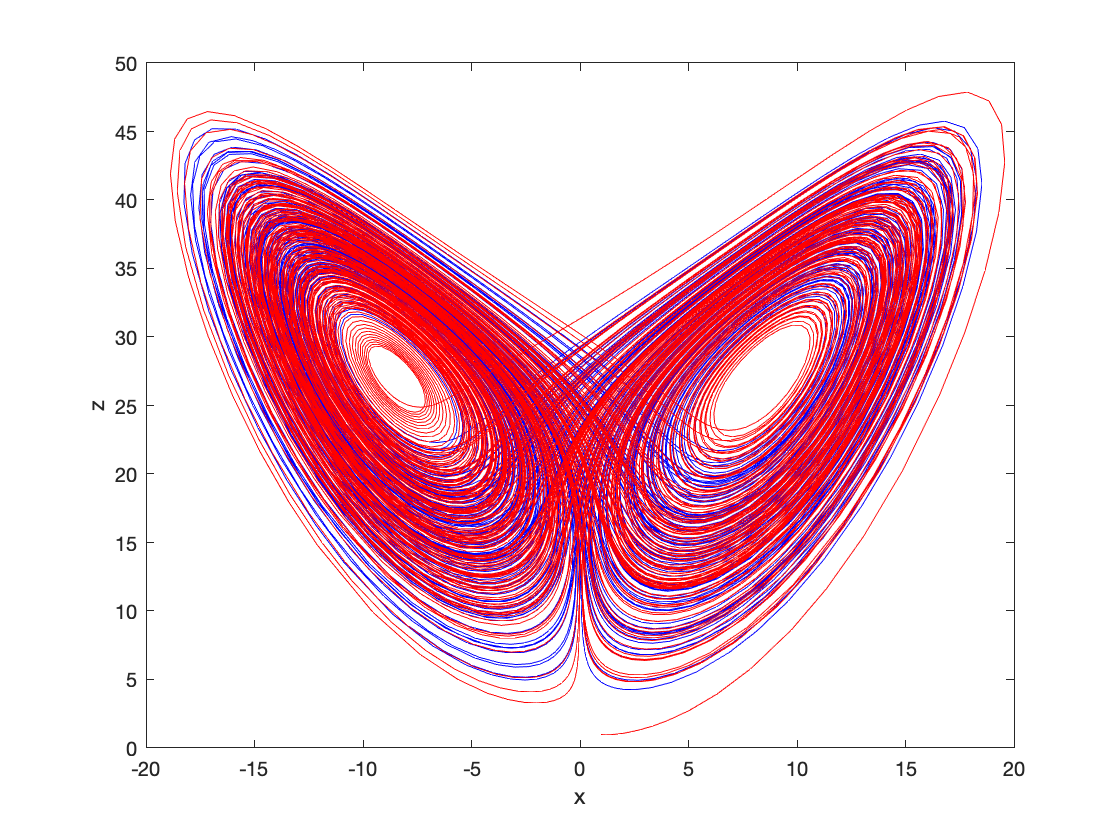

% Set the parameters 
s = 10.0;
b = 8.0/3.0;
r = 28.0;
 
% Set the time span
t_init = 0.0;
t_final = 200.0;
t_span = [t_init t_final];

% Choose two sets of initial conditions that are very close to each other.
y_init1 = [1.0; 1.0; 1.0];
y_init2 = [1.0+1.0e-6; 1.0; 1.0];

% Solve the equations for the two sets of initial conditions.
[t1,y1] = ode45(@(t,y) LorenzEqns(t, y, s, b, r), t_span, y_init1);
[t2,y2] = ode45(@(t,y) LorenzEqns(t, y, s, b, r), t_span, y_init2);
 
% Plot the results from the two solutions on top of each other
figure
plot(y1(:,1), y1(:,3), 'b', y2(:,1), y2(:,3), 'r')
xlabel('x');
ylabel('z');

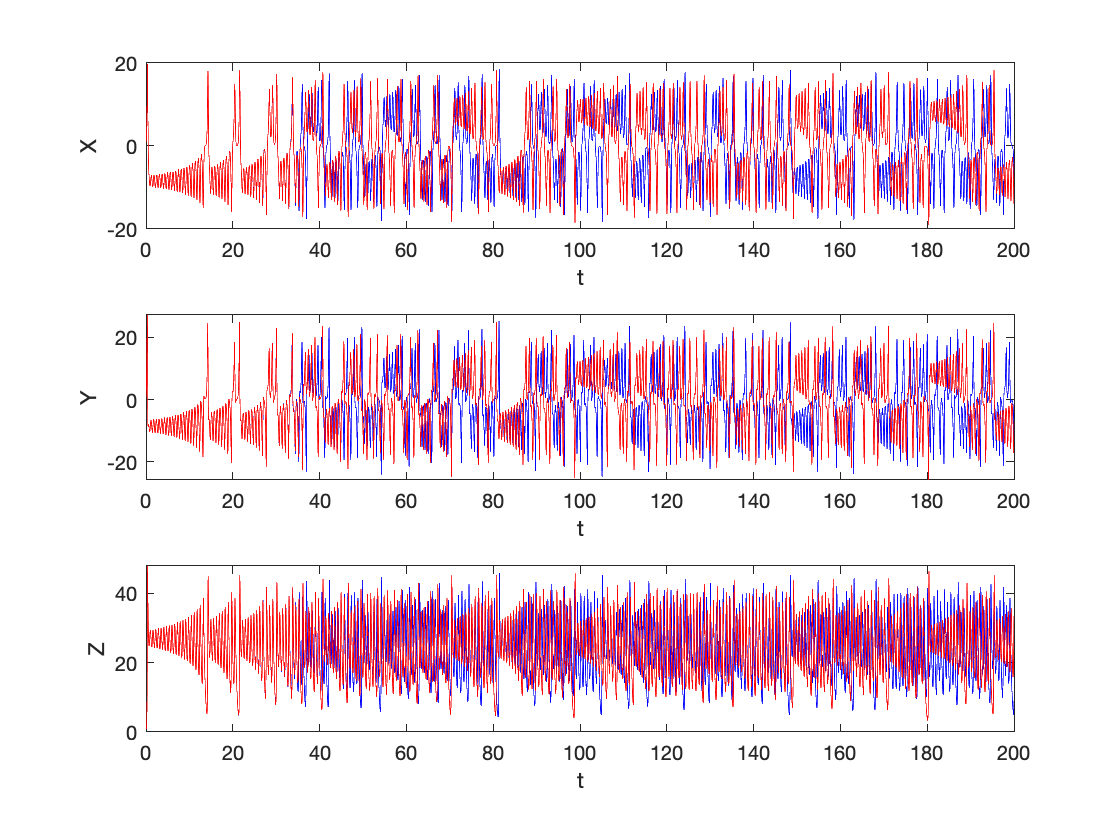

% Plot the time evolution of the three variables separately. 
figure
subplot(3,1,1)
plot(t1, y1(:,1), 'b', t2, y2(:,1), 'r')
xlabel('t')
ylabel('X')
 
subplot(3,1,2)
plot(t1, y1(:,2), 'b', t2, y2(:,2), 'r')
xlabel('t')
ylabel('Y')
 
subplot(3,1,3)
plot(t1, y1(:,3), 'b', t2, y2(:,3), 'r')
xlabel('t')
ylabel('Z')

We can see from these plots that the trajectories from the two solutions initially lie on top of each other (you can only see one colour), but as time increases, they become separate and follow very different paths. This is an example of *sensitive dependence on initial conditions *and is an example of one route to chaotic behavior. In essence, the system is unstable, but also constrained within a particular set of values of x, y, and z. As a result, the two different trajectories cannot diverge to infinity, but instead move around this space (e.g. as shown in the butterfly diagram) taking very different paths. 

***Exercise:**** Repeat the example above but using the parameter value r = 20.0 and compare your results with the ones shown. *